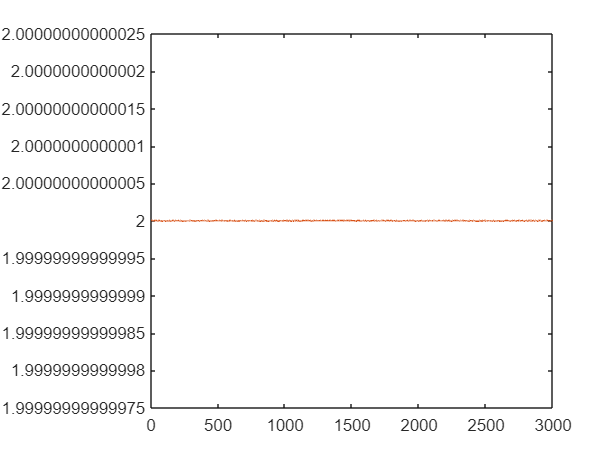

H1 = PauliI(2, 1, 3) * PauliI(2, 2, 3); % H1 = Z1Z2
H2 = -PauliI(2, 1, 3) * PauliI(2, 2, 3);

H1 = diag([3,0,5,1]);
H2 = diag([3,5,0,1]);
lam = 0.5; % Schmidt eigenvalue
% extreme cases: 0 for coorperate, 1 for defect
   
InitialState = @(lam) sqrt(lam) * [0;0;0;1] + sqrt(1-lam) * [1;0;0;0];

psi_0 = InitialState(lam);
niter = 3000;
N = 2;
eps = 10e-2*exp(-linspace(0,1,niter)/2);

GamePayoff = {H1, H2};
GameState = zeros(4, niter);
GamePayoffData = zeros(2, niter);
GameStrategy = {zeros(2, 2, niter), zeros(2, 2, niter)};

% define update in the direction of a for player i
upd = @(game_state,i) vphi(GamePayoff,game_state,N,i);
upd_v1 = @(game_state,i) vphi_v1(GamePayoff,game_state,N,i);

% initialize
GameStrategy{1}(:,:,1) = eye(2);
GameStrategy{2}(:,:,1) = eye(2);
GameState(:,1) = InitialState(lam);

% GameState(:,1) = 1-2*rand(4,1);
% GameState(:,1) = GameState(:,1)/norm(GameState(:,1));

GamePayoffData(1,1) = GameState(:,1)'*GamePayoff{1}*GameState(:,1);
GamePayoffData(2,1) = GameState(:,1)'*GamePayoff{2}*GameState(:,1);

% play the game smoothly
version = 1;
for iter = 2:niter
    switch version
        case 1
            for i = 1:N
                v = upd_v1(GameState(:,iter-1),i);
                %v = upd(GameState(:,iter-1),i);
                GameStrategy{i}(:,:,iter) =expm(1i*eps(iter)*v)*GameStrategy{i}(:,:,iter-1);
            end
        case 0
            for i = 1:N
                v = zeros(2);
                for a = 1:3
                    val = vphi_v0(GamePayoff,GameState(:,iter-1),N,i,a);
                    v = v + val*PauliI(1,1,a);
                end
                GameStrategy{i}(:,:,iter) = expm(1i*eps(iter)*v)*GameStrategy{i}(:,:,iter-1);
            end
    end
                
    GameState(:,iter) = kron(GameStrategy{1}(:,:,iter),GameStrategy{2}(:,:,iter)) * GameState(:,1);
    GameState(:,iter) = GameState(:,iter)/norm(GameState(:,iter));

    for i = 1:N
        GamePayoffData(i,iter) = GameState(:,iter)'*GamePayoff{i}*GameState(:,iter);
    end
end

plot(0:niter-1,real(GamePayoffData))

Ok it seems that the first order derivative is not enough to characterize the

function sigma_dir = vphi(GamePayoff,game_state,N,i)
iPayoff = GamePayoff{i};
% second order derivative is not this..
% val = max(0, -game_state'*comm(comm(iPayoff,PauliI(N,i,a)),PauliI(N,i,a))*game_state);
val_1 = zeros(1,3);
val_2 = zeros(1,3);
for a = 1:3
    val_1(a) = max(0,1i*game_state'*comm(iPayoff,PauliI(N,i,a))*game_state);
    val_2(a) = max(0,game_state'*comm(comm(iPayoff,PauliI(N,i,a)),PauliI(N,i,a))*game_state);
end
sigma_dir = zeros(2);
if norm(val_1) > 1e-10
    val_1 = val_1/norm(val_1);
    sigma_dir = val_1(1) * [0,1;1,0] + val_1(2) * [0,-1i;1i,0] + val_1(3) * [1,0;0,-1];
elseif norm(val_2) > 1e-10
    val_2 = val_2/norm(val_2);
    sigma_dir = val_2(1) * [0,1;1,0] + val_2(2) * [0,-1i;1i,0] + val_2(3) * [1,0;0,-1];
end
end

function A = comm(X,Y)
A = X*Y-Y*X;
end

% a second order scheme, given that we sit at the Nash equilibria point
function sigma_dir = vphi_v1(GamePayoff,game_state,N,i)
iPayoff = GamePayoff{i};
paulis = {[0,1;1,0],[0,-1i;1i,0],[1,0;0,-1]};

val_1 = zeros(1,3);
for a = 1:3
    val_1(a) = max(0,1i*game_state'*comm(iPayoff,PauliI(N,i,a))*game_state);
end

if norm(val_1) > 1e-10
    val_1 = val_1/norm(val_1);
    sigma_dir = val_1(1) * [0,1;1,0] + val_1(2) * [0,-1i;1i,0] + val_1(3) * [1,0;0,-1];
else
    % 1st order quantity vanishes, try going to second order
    val_2 = zeros(3);
    for a = 1:3
        for b = 1:3
            val_2(a,b) = 1/2*game_state'*(2*PauliI(N,i,a)*iPayoff*PauliI(N,i,b)-PauliI(N,i,a)*PauliI(N,i,b)*iPayoff-iPayoff*PauliI(N,i,a)*PauliI(N,i,b))*game_state;
        end
    end
    % we have the hessian matrix as val_2, now find the highest eigenvalue
    % to give an optimal direction for the strategies to move.

    % update 11/20/2023: symmetrize the matrix
    [spec,lam] = eig((val_2+val_2.')/2,'vector');
    [l,indl] = max(lam);
    vec = (l>0)*spec(:,indl);
    sigma_dir = vec(1)*paulis{1} + vec(2)*paulis{2} + vec(3)*paulis{3};
end

end

function val = vphi_v0(GamePayoff,game_state,N,i,a)
iPayoff = GamePayoff{i};
% second order derivative is not this..
val = max(0, -game_state'*comm(comm(iPayoff,PauliI(N,i,a)),PauliI(N,i,a))*game_state);

end